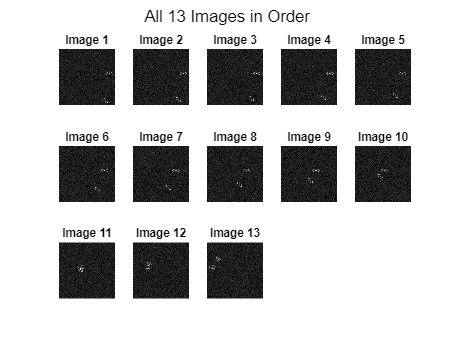

% Step 1: Set the current folder
image_folder = fullfile('F:', 'Downloads', 'MATLAB', 'Image-Processing-HW3', 'img');
cd(image_folder);

% Step 2: Get a list of all JPEG images in the folder
image_files = dir('*.jpeg');

% Step 3: Extract numeric values from the filenames and sort them
file_names = {image_files.name}; % Get all filenames
numeric_part = zeros(1, length(file_names));

% Loop through each filename to extract the numeric part
for i = 1:length(file_names)
    % Extract the numeric part using regex
    numeric_part(i) = sscanf(file_names{i}, '%d');
end

% Sort filenames by the numeric part
[~, sorted_indices] = sort(numeric_part);
sorted_file_names = file_names(sorted_indices);

% Step 4: Preallocate a cell array to store the images
num_images = length(sorted_file_names);
images = cell(1, num_images);

% Step 5: Read and store each image in the sorted order
for i = 1:num_images
    % Construct the full file name
    file_name = fullfile(image_folder, sorted_file_names{i});
    
    % Read the image
    images{i} = imread(file_name);
end

% Step 6: Plot all images in a subplot
figure;
rows = 3;
cols = 5;

for i = 1:num_images
    subplot(rows, cols, i);
    imshow(images{i});
    title(sprintf('Image %d', numeric_part(sorted_indices(i))));
end

% Optional: Add a global title to the figure
sgtitle('All 13 Images in Order');